## **POC 3**

data_file       = '../data/v3/230920_16042025.csv';
meta_file       = '../data/v3/230920_16042025.json';
output_path     = 'output/ddindd';
addpath("ddindd/");

%%% READ INPUTS
try
    data        = readtable( data_file, Delimiter = ',');
catch e
    error("[ERROR][data reader] " + convertCharsToStrings(e.message));
end


try
    metadata    = jsondecode( fileread( meta_file ) );
catch e
    disp("[WARNING][metadata reader] " + convertCharsToStrings(e.message));
    metadata    = {};
end

%%% DDINDD
d   = ddindd(data, method = 'langmuir', metaFile = metadata, relInj = 0);

[WARNING][func fit] No matching data for round 8 and injection type Negative sample



%%% PLOTDDINDD

%% GetValue: get value from struct or, if not available, set default
%
% Args:
%       s (struct): struct where input is from
%       path (char): path to relevant struct field ex.: 'path1.path2'}
%       defaultValue (any): default value, if value from struct not available
%
% Returns:
%       value (any): value to use
%
function value = GetValue(s, path, defaultValue)
    keys = strsplit(path, '.');
    try
        value = getfield(s, keys{:});
    catch
        value = defaultValue;
    end
end

%% GetInjectionType: Return injection type
%
% Args:
%       i (int): injection type integer
%
% Result:
%       inj_type (string): injection type string
%
function inj_type = GetInjectionType(i)
    switch i
        case 0
            inj_type = "Negative sample";
        case 1
            inj_type = "Positive sample";
        case 3
            inj_type = "Flush";
        case 4
            inj_type = "Urea";
        otherwise
            inj_type = "Unknown";
    end
end


shortFileId     = GetValue(d, 'meta.shortFileId', "NaN"); % "193";
dateStr         = GetValue(d, 'meta.dateStr', "0000-00-00"); % "2025-05-23";

injections      = GetValue(d, 'meta.injections', []); 

relInj          = GetValue(d, 'meta.relInj', 0); % int;

fitFunction     = GetValue(d, 'meta.method', {"no fit function found"}); % "Langmuir";
fitFunctionH    = GetValue(d, 'meta.methodFunc', 0); % function handle
fitFunctionEx   = GetValue(d, 'meta.methodEx', {"no ex for fit function found"}); % "b*(1-e^(-(k*(x-t))";

n_rounds        = GetValue(d, 'meta.n_rounds', 2); % 2; 
nRoundsStr      = convertCharsToStrings(num2str(n_rounds));

n_sensors       = GetValue(d, 'meta.n_sensors', 8); % 8;

data            = GetValue(d, 'raw', data);

drift_sp_T = cell(n_rounds, n_sensors); sp_corr_T = cell(n_rounds, n_sensors); best_a_T = cell(n_rounds, n_sensors); best_b_T = cell(n_rounds, n_sensors); rsquared_T = cell(n_rounds, n_sensors);
    for r = 1:n_rounds
        round = "round" + r;
        for s = 1:n_sensors
            sensor = "sensor" + s;
            drift_sp_T{r, s}    = GetValue(d, char(round + "." + sensor + "." + "driftSP"), NaN); % d.(round).(sensor).driftSP
            sp_corr_T{r, s}     = GetValue(d, char(round + "." + sensor + "." + "SPcorr"), NaN); % d.(round).(sensor).SPcorr
            best_a_T{r, s}      = GetValue(d, char(round + "." + sensor + "." + "a"), NaN); % d.(round).(sensor).a
            best_b_T{r, s}      = GetValue(d, char(round + "." + sensor + "." + "b"), NaN); % d.(round).(sensor).b
            rsquared_T{r, s}    = GetValue(d, char(round + "." + sensor + "." + "Rsquared"), NaN); % d.(round).(sensor).Rsquared;
        end
    end

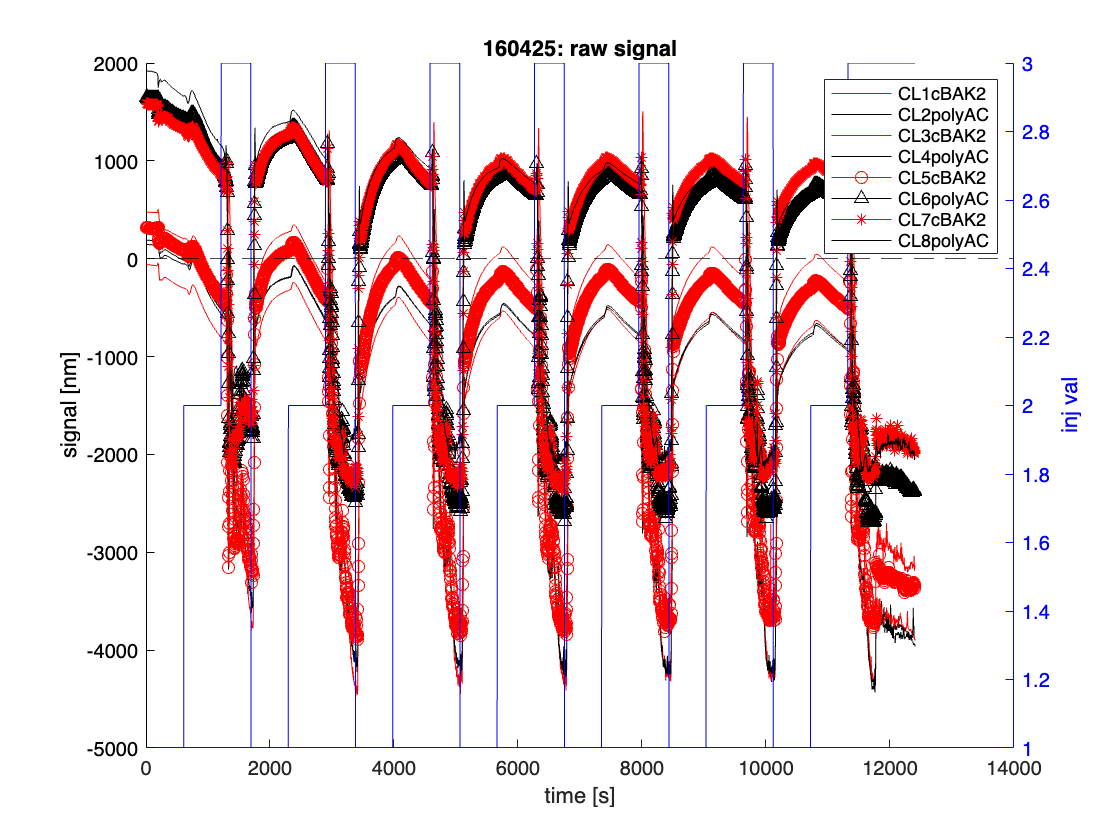

%%% plot raw
figure; hold on; colororder({'k','b'}); yyaxis left;
colmap = repmat([1 0 0; 0 0 1], d.meta.n_sensors, 1);
% markermap = {'o', '+', 'square', 'x', 'diamond', '*', '^', '|', '>', '<',
% 'v', 'hexagram', '.'}; % Marker = markermap(i), MarkerSize = 2,
for i = 1:8
    plot(data.("T_s_"), data{:, i+4}, Color = colmap(i, :), LineStyle = '-', DisplayName = data.Properties.VariableNames{i+4}); 
end
ylabel("signal [nm]");
yline(0, 'k--', HandleVisibility = 'off');
yyaxis right; plot(data.("T_s_"), data{:, "Val_"}, Color = 'b', HandleVisibility = 'off');
legend(); ylabel("inj val"); xlabel("time [s]"); title(d.meta.shortFileId + ": raw signal")

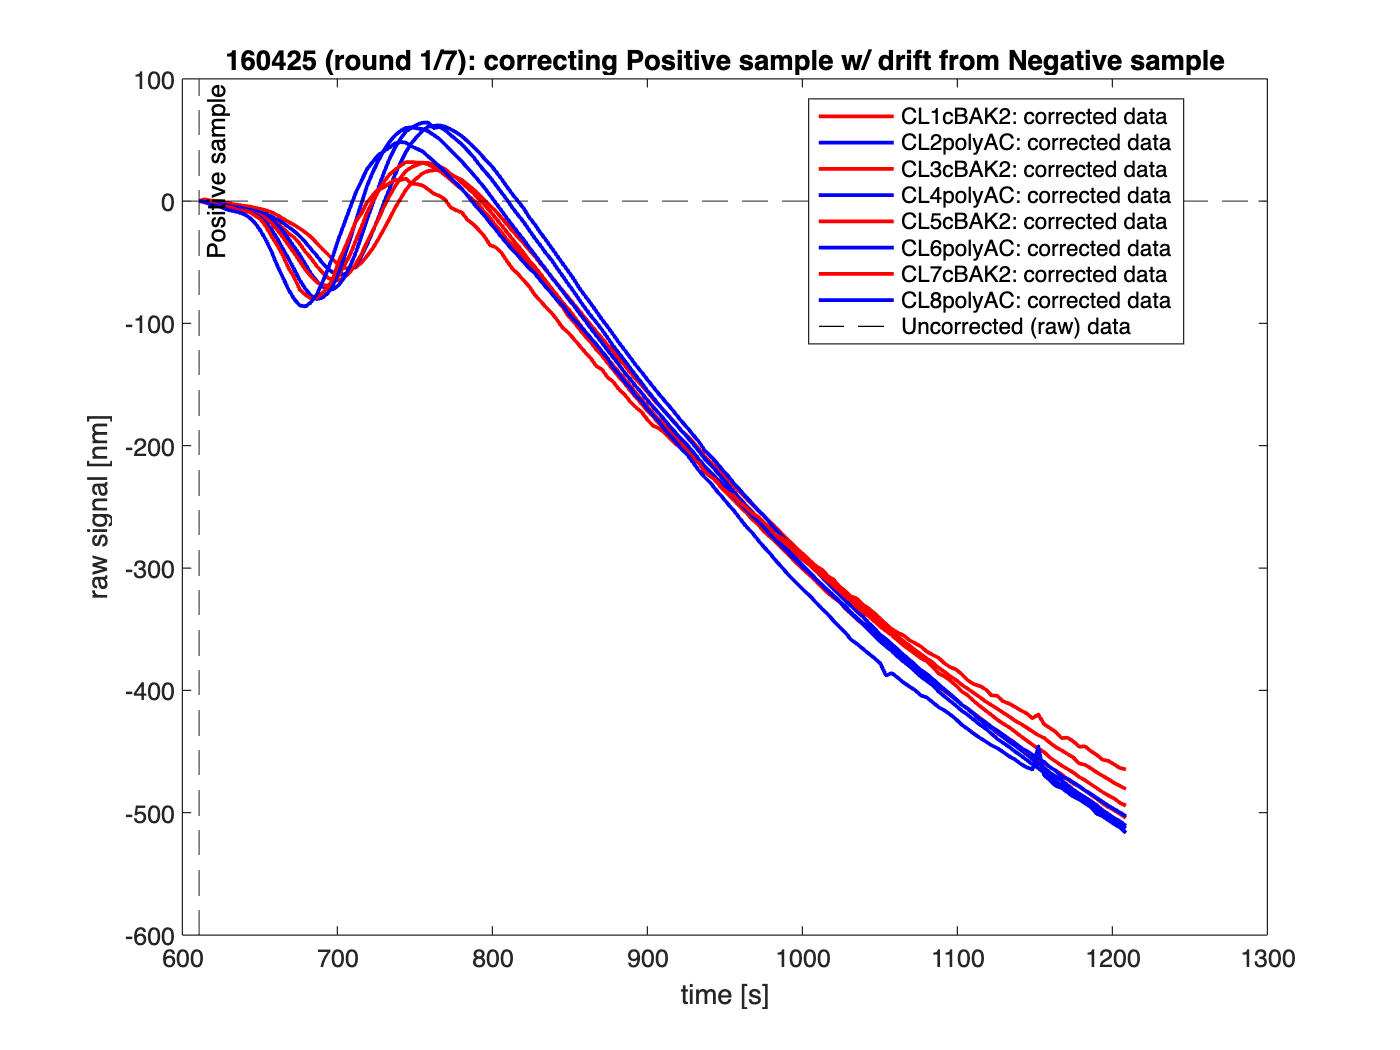

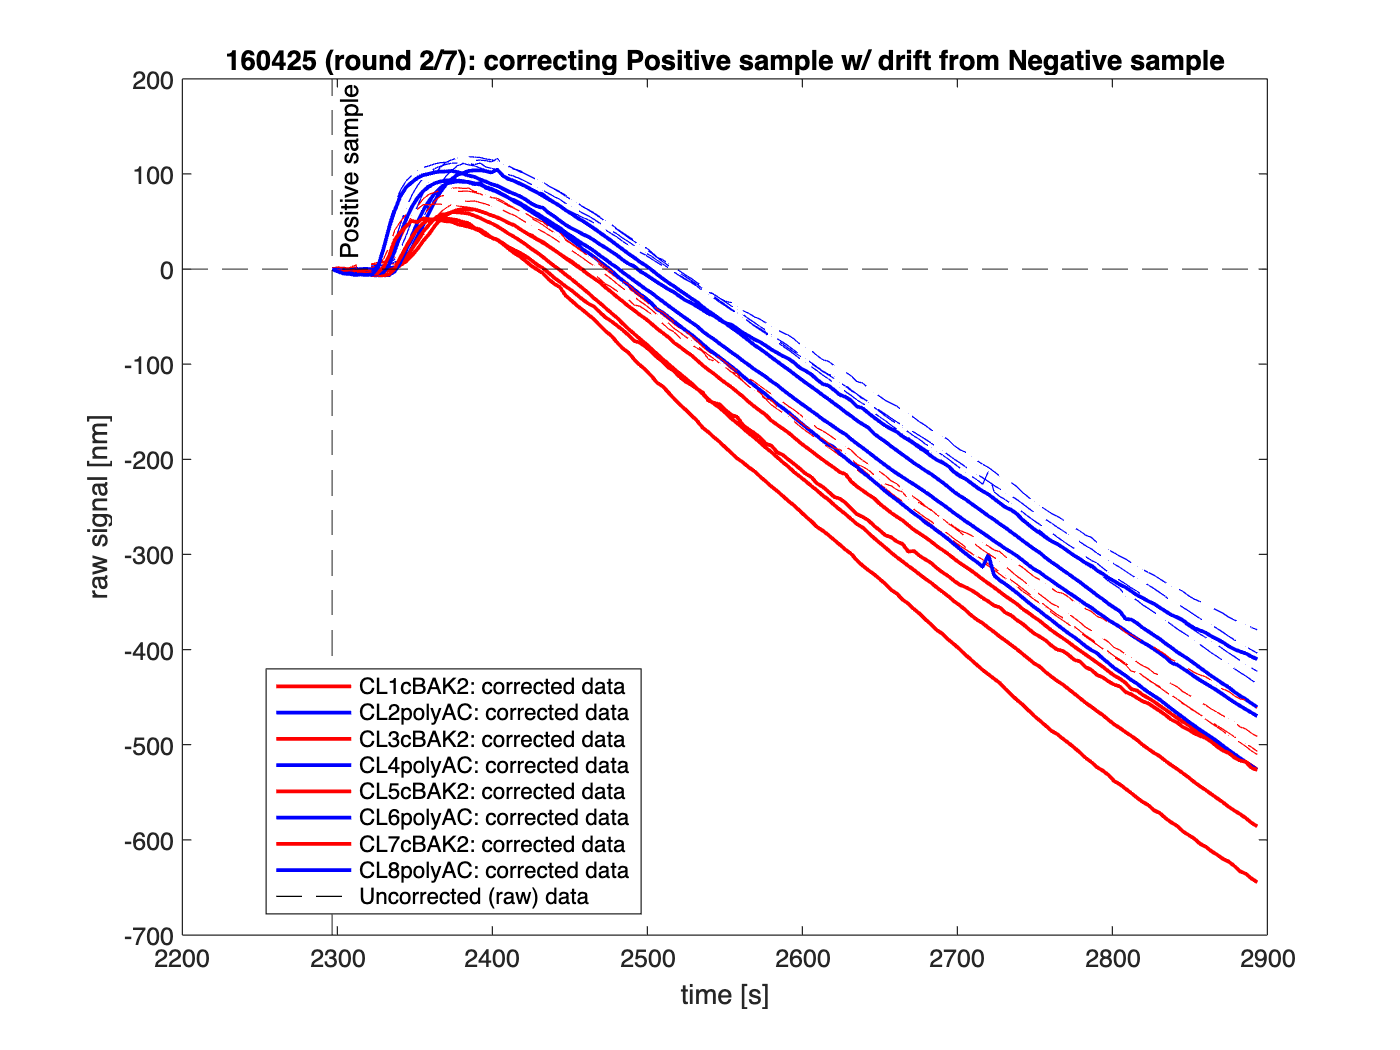

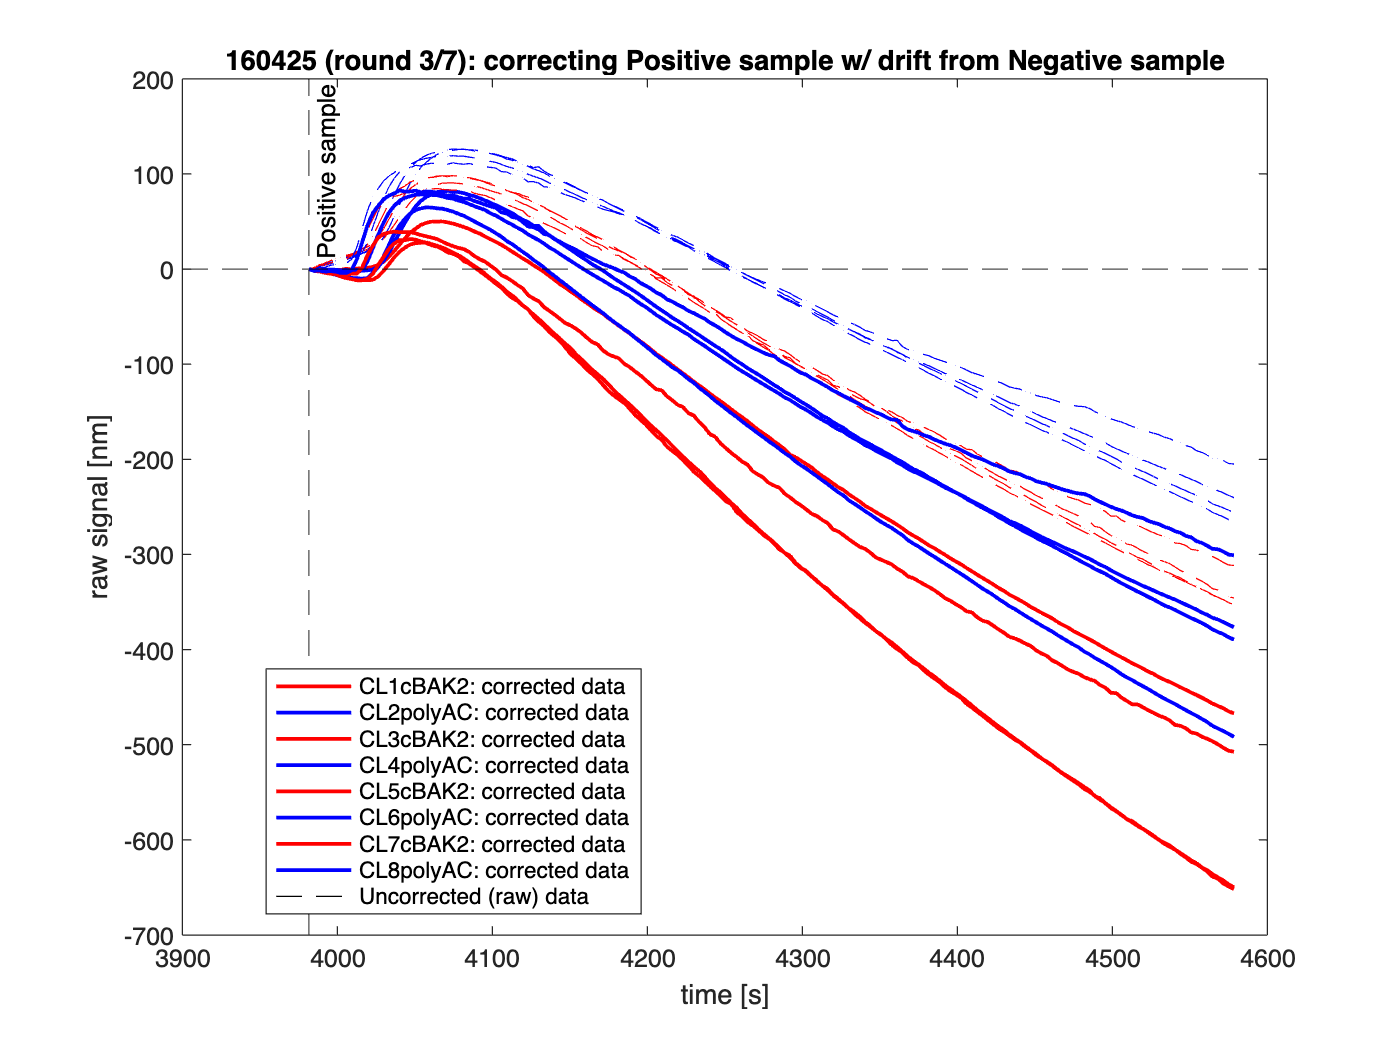

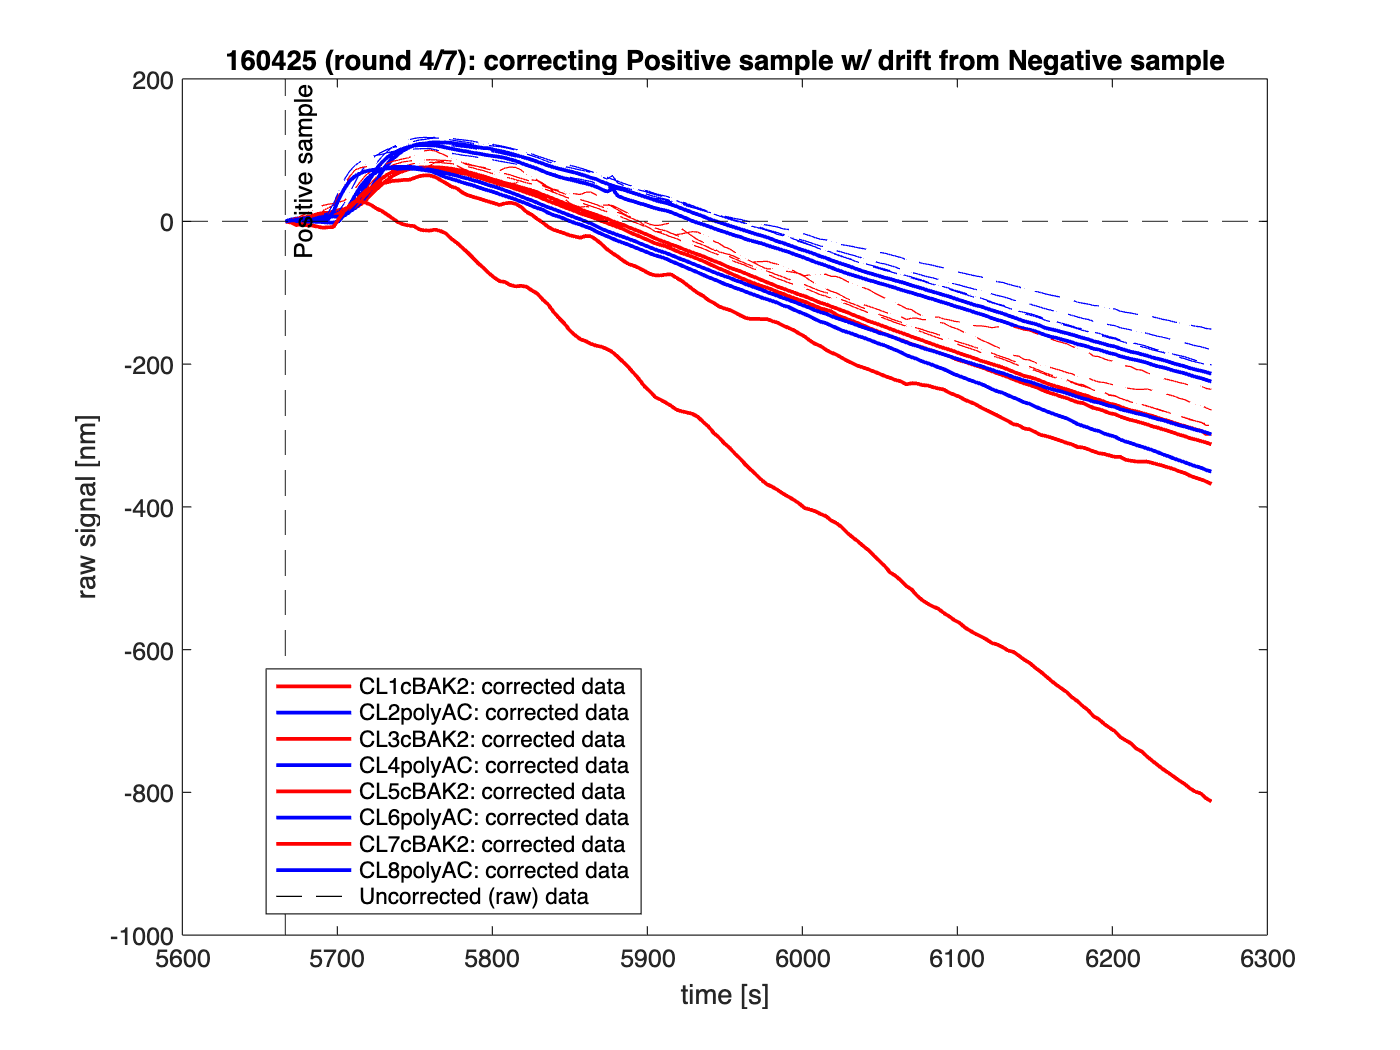

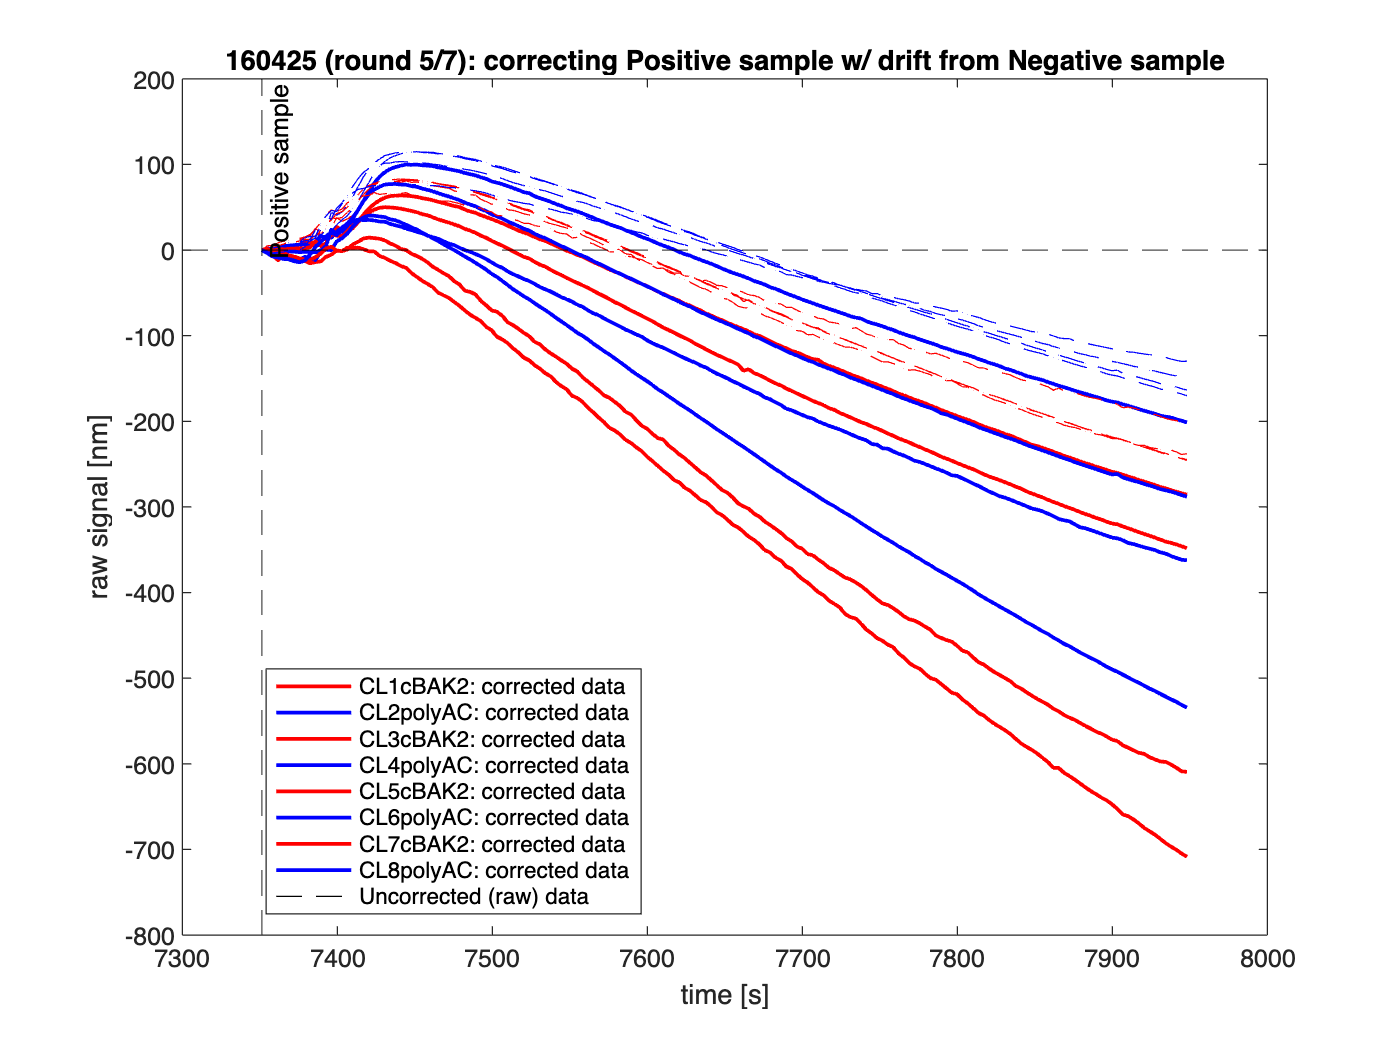

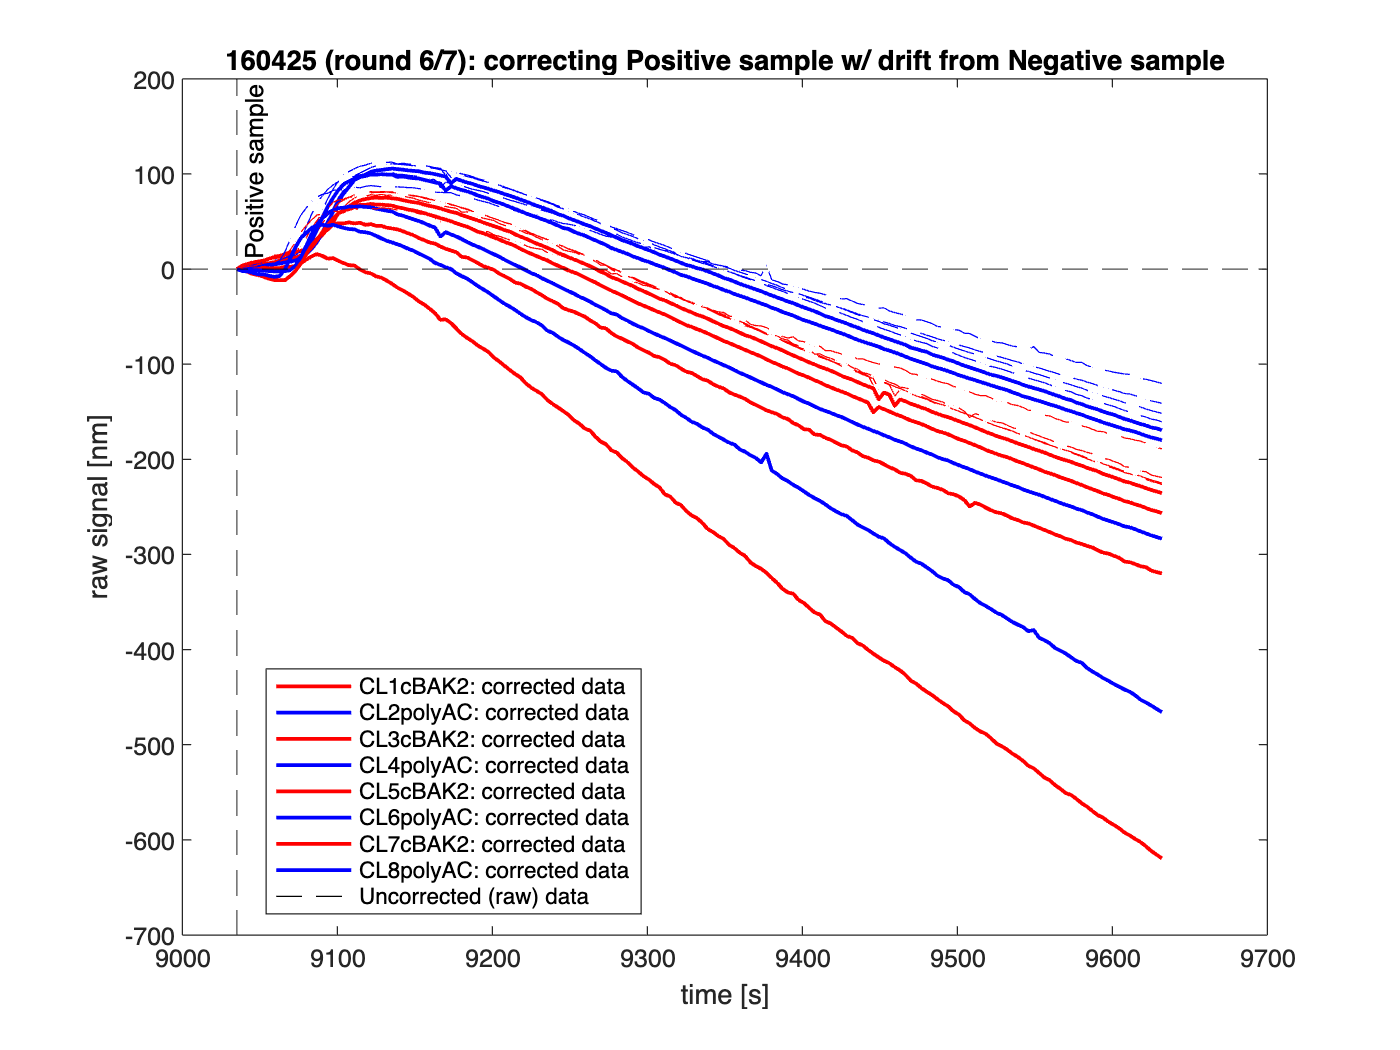

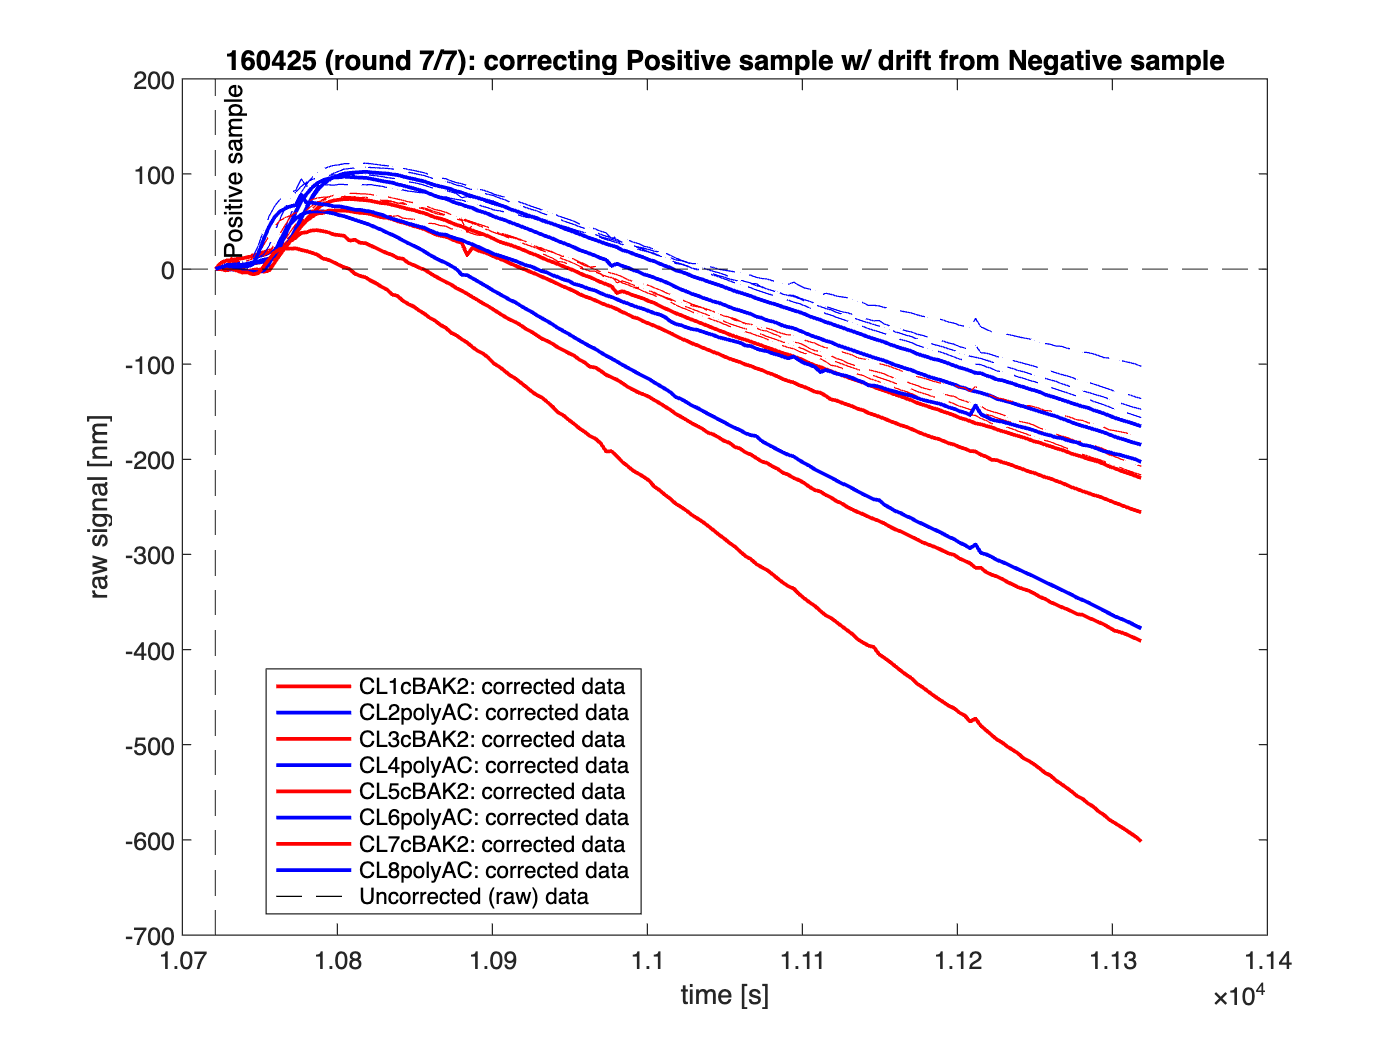

plotddindd(d, plotType = 1, plotMarker = 0, plotUncorrToo = 1);

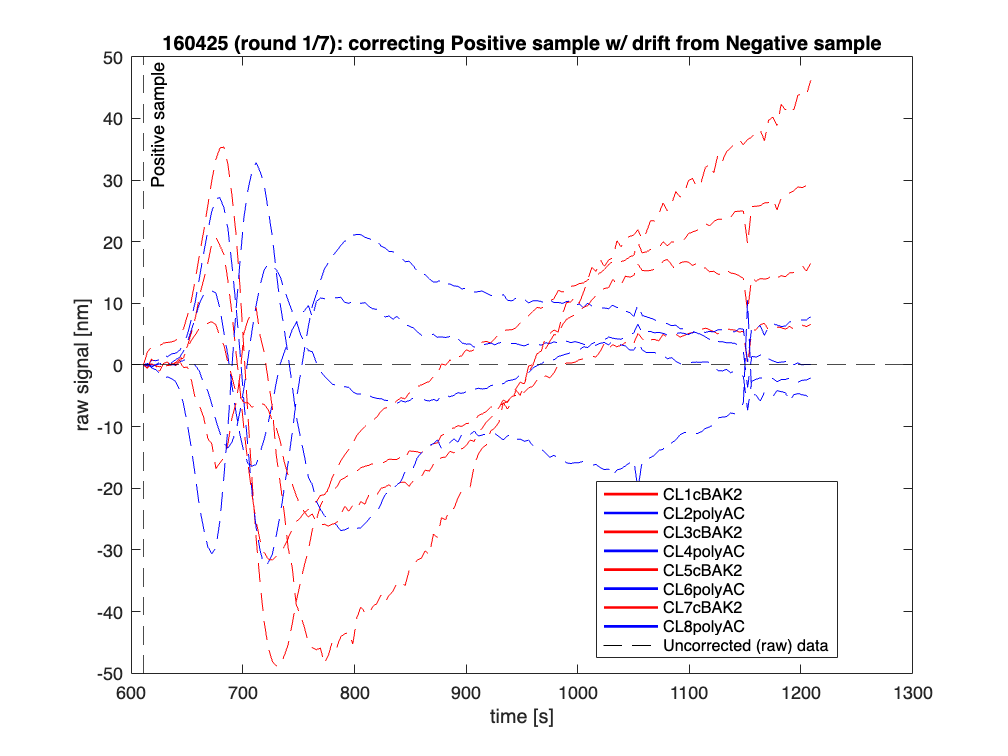

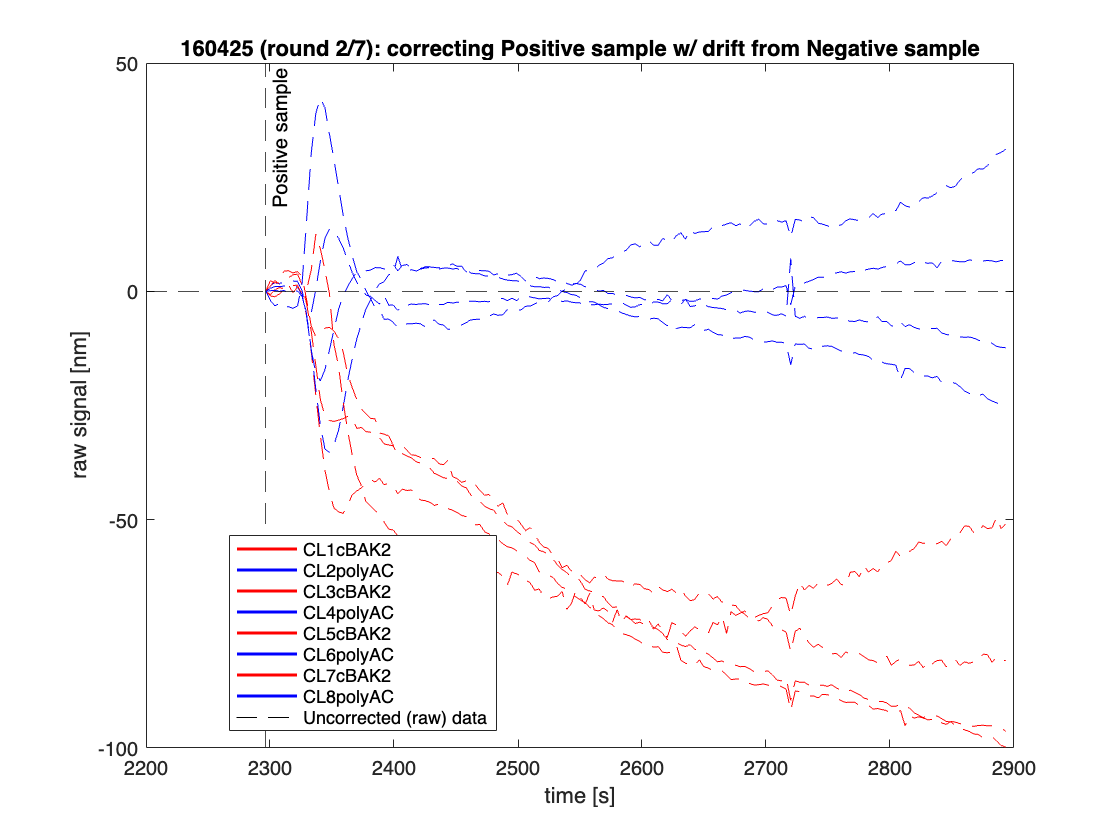

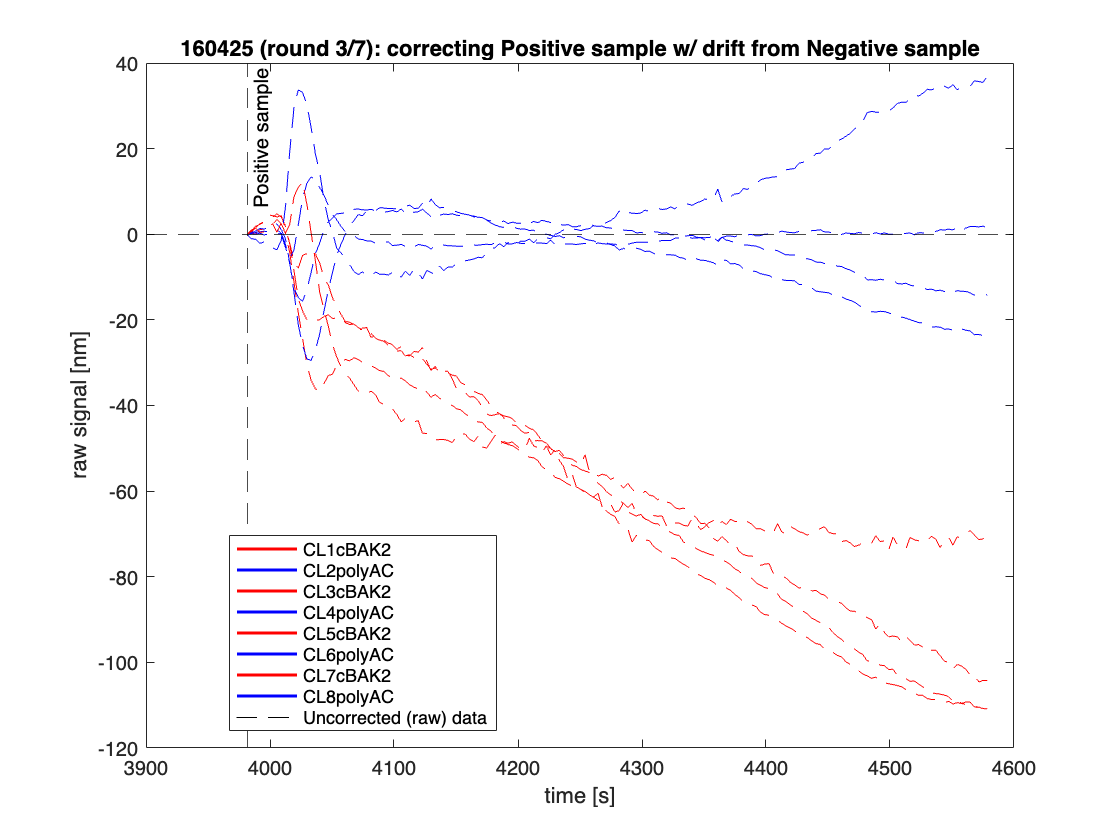

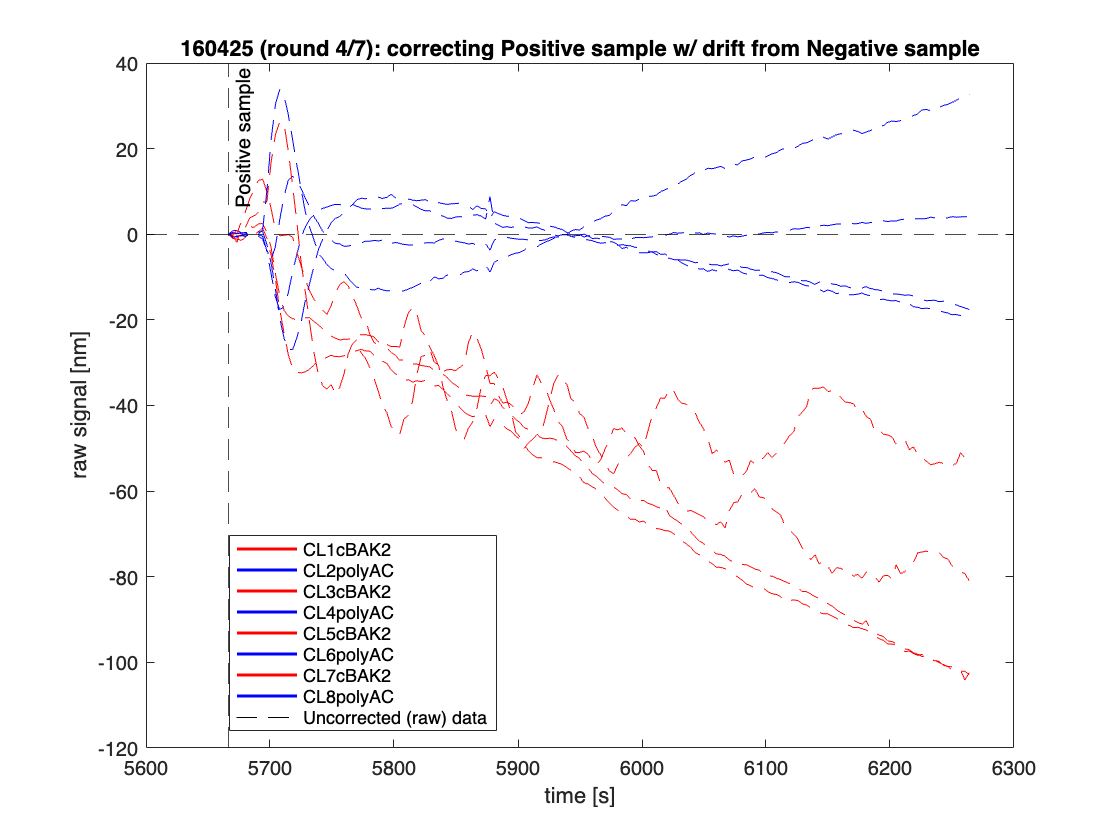

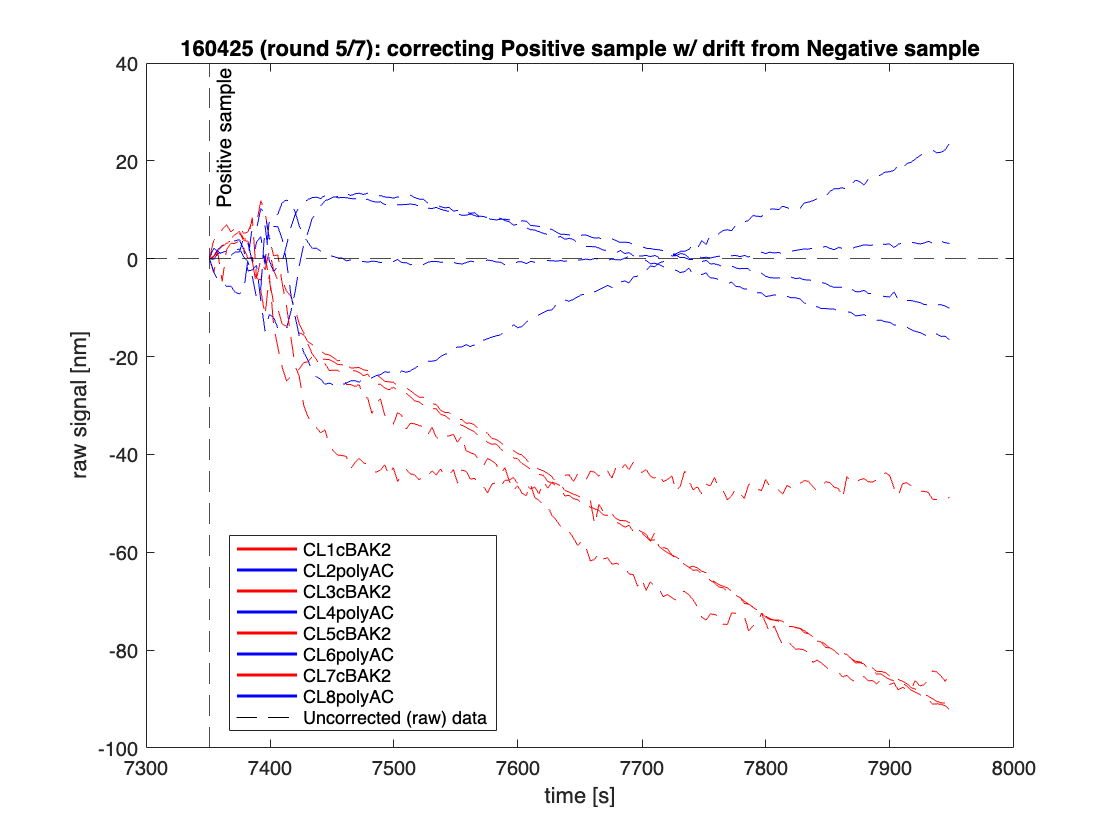

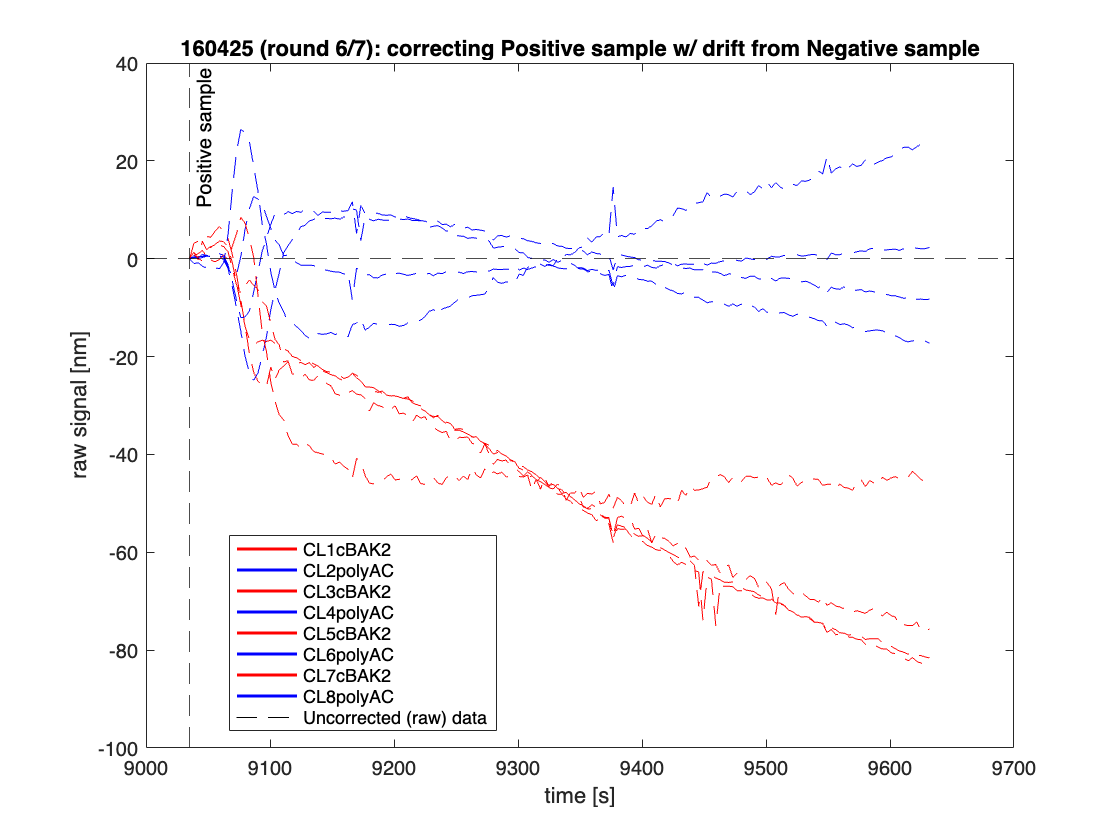

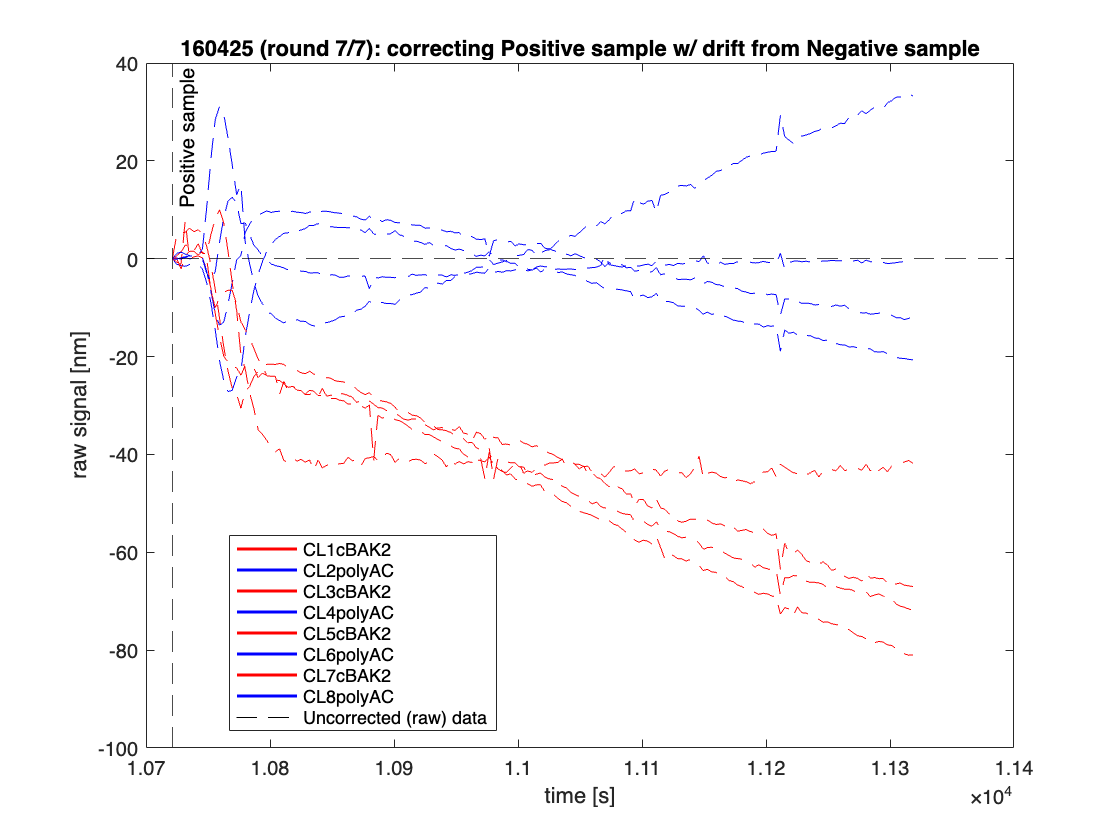

%%% subtract mean of differentials
colmap          = repmat([1 0 0; 0 0 1], n_sensors, 1);
markermap       = {'o', '+', 'square', 'x', 'diamond', '*', '^', '|', '>', '<', 'v', 'hexagram', '.'};

plotMarker      = 0;
plotCorrToo     = 0;
plotFitToo      = 0;
plotUncorrToo   = 1;
plotCorrType    = 1;

plotSensors     = [1:n_sensors];
plotRounds      = [1:n_rounds];

for r = plotRounds
    round = "round" + r;

    clf(figure(r));             % clear figure
    H{r}        = figure(r);    % create figure for round
    fig_handles = [];           % create empty array for handles

    % load data
    pltData     = data(data.round == r & (data.inj_type == relInj | data.inj_type == plotCorrType), :);  
    plttgLength = height(data);

    relInjEnd   = find(diff(pltData.inj_type) ~= 0) + 1;

    mu_array = mean([pltData{:, [6, 8, 10, 12]}], 2);

    for s = plotSensors
        sensor      = "sensor" + s; 
        sensor_name = pltData.Properties.VariableNames{s+4};

        strVal      = GetValue(d, char(round + "." + sensor + "." + "strVal"), 0);

        posBeginn   = find(diff(pltData.inj_type == plotCorrType) == 1) + 1;
        posStrVal   = pltData{posBeginn, s+4};

        if plotUncorrToo
            if plotMarker
                plot(pltData{posBeginn:end, "T_s_"}, pltData{posBeginn:end, s+4} - posStrVal - mu_array(posBeginn:end) + mu_array(posBeginn), Color = colmap(s, :), Marker = markermap{s}, LineStyle = '--', HandleVisibility = 'off'); hold on;
            else
                plot(pltData{posBeginn:end, "T_s_"}, pltData{posBeginn:end, s+4} - posStrVal - mu_array(posBeginn:end) + mu_array(posBeginn), Color = colmap(s, :), Marker = 'none', LineStyle = '--', HandleVisibility = 'off'); hold on;
            end
        end

        % calc model
        t_rel       = (1:(length(pltData.T_s_) - drift_sp_T{r, s} + 1))';
        model       = fitFunctionH;
        y_model     = model(best_a_T{r, s}, best_b_T{r, s}, t_rel);

        % add zeros at beginning and strVal correction 
        y_model     = [zeros(drift_sp_T{r, s}-1, 1); y_model];

        if plotFitToo
            % plot fit
            if plotMarker
                plot(pltData{posBeginn:end, "T_s_"}, y_model(posBeginn:end) - mu_array(posBeginn:end) + mu_array(posBeginn), ':k', Marker = markermap{s}, HandleVisibility = 'off');
            else
                plot(pltData{posBeginn:end, "T_s_"}, y_model(posBeginn:end) - mu_array(posBeginn:end) + mu_array(posBeginn), ':k', Marker = 'none', HandleVisibility = 'off');
            end
        end

        % plot result
        if plotCorrToo || (~plotCorrToo && ~plotUncorrToo && ~plotFitToo)
            if plotMarker
                h = plot(pltData{posBeginn:end, "T_s_"}, pltData{posBeginn:end, s+4} - y_model(posBeginn:end) - posStrVal + y_model(posBeginn) - mu_array(posBeginn:end) + mu_array(posBeginn), Color = colmap(s, :), Marker = markermap{s}, LineStyle = '-', LineWidth = 1.5, DisplayName = sensor_name + ": corrected data"); hold on; 
            else
                h = plot(pltData{posBeginn:end, "T_s_"}, pltData{posBeginn:end, s+4} - y_model(posBeginn:end) - posStrVal + y_model(posBeginn) - mu_array(posBeginn:end) + mu_array(posBeginn), Color = colmap(s, :), Marker = 'none', LineStyle = '-', LineWidth = 1.5, DisplayName = sensor_name + ": corrected data"); hold on;
            end
        else
            if plotMarker
                h = plot(NaN, NaN, Color = colmap(s, :), Marker = markermap{s}, LineStyle = '-', LineWidth = 1.5, DisplayName = sensor_name); hold on;
            else
                h = plot(NaN, NaN, Color = colmap(s, :), Marker = 'none', LineStyle = '-', LineWidth = 1.5, DisplayName = sensor_name); hold on;
            end
        end
        fig_handles = [fig_handles h];
    end

    if plotUncorrToo
        h = plot(NaN, NaN, Color = 'k', Marker = 'none', LineStyle = '--', DisplayName = "Uncorrected (raw) data"); % handle for legend
        fig_handles = [fig_handles h];
    end

    if plotFitToo
        h = plot(NaN, NaN, Color = 'k', Marker = 'none', LineStyle = ':', DisplayName = "Data fit"); % handle for legend
        fig_handles = [fig_handles h];
    end
    
    yline(0, Color = 'k', LineStyle = '--', HandleVisibility = 'off'); % add 0 base line

    xline(pltData.T_s_(posBeginn), Color = 'k', LineStyle = '--', HandleVisibility = 'off', Label = GetInjectionType(plotCorrType));

    title(shortFileId + " (round " + r + "/" + n_rounds + "): correcting " + GetInjectionType(plotCorrType) + " w/ drift from " + GetInjectionType(relInj));
    xlabel("time [s]"); ylabel("raw signal [nm]");
    legend(fig_handles, 'Location', 'best');

    hold off;

end


differentials = table();
for s = 1:(d.meta.n_sensors/2)
    for u = 1:(d.meta.n_sensors/2)
        diff_array = data{:, 2*s+3} - data{:, 2*u+4};
        array_name = "diff_s" + string(2*s+3) + "_s" + string(2*u+4); differentials.("diff_s" + string(2*s-1) + "_s" + string(2*u)) = diff_array;
    end
    mu_array = mean([data{:, [6, 8, 10, 12]}], 2);
    diff_array = data{:, 2*s+3} - mu_array;
    array_name = "diff_s" + string(2*s-1) + "_mu"; differentials.("diff_s" + string(2*s-1) + "_mu") = diff_array;
end